clc
clear all
close all
% Raflooor Viability calculator
% Live prices of BNTX and Solana token currently just taken from user at
% start of script but can use CMC to automatically retrieve
Solana_Price = 12.29;    % $
BNTX_Price = 0.00041056; % $ 
BHSG_FP = 2.94;          % Sol

% Specifies some current prices in other metrics along with tickets amounts
% and allocations in terms of if you own them or not
Your_Tickets = input("How many tickets have you purchased? ");
Current_Tickets = input("How many tickets have been purchased? ");
Current_FP_USD = BHSG_FP * Solana_Price;
Current_FP_BNTX = Current_FP_USD / BNTX_Price;
Current_Tickets_BNTX = Current_Tickets * 250;

% Determines a ticket saturation in terms of percent compared to BHSG FP
Saturation = (Current_Tickets_BNTX / Current_FP_BNTX) * 100;
Ideal_Saturation_Tickets = floor(Current_FP_BNTX / 250);
fprintf("The current raffle is %.2f%% saturated\n",Saturation)

The current raffle is 71.02% saturated


fprintf("The ideal number of tickets for the current FP is %.f%",Ideal_Saturation_Tickets)

The ideal number of tickets for the current FP is 352


% How many tickets do you need to buy to get to the ideal saturation? You
% can take your tickets along with the tickets that have already been
% bought away from the ideal saturation and return a estimated number of
% tickets to buy that gives you the maximum economically viable chance
% which still has the greatest chance to win
Tickets_to_Buy = Ideal_Saturation_Tickets - Current_Tickets;
Win_Probability = (Your_Tickets / Current_Tickets) * 100; 
fprintf("You should buy %i tickets for the greatest statistically viable chance", Tickets_to_Buy)

You should buy 102 tickets for the greatest statistically viable chance

fprintf("You currently have %.2f%% of a chance to win",Win_Probability)

You currently have 40.00% of a chance to win


% The maximum tickets for any given raffle is 5000 tickets with a 1.25m
% BNTX evaluation for the maximum bound at roughly ~37.5 sol at current
% prices with a 8.64% price move impact on raydium

% The chance of winning from the current tickets is recursively calculated
% for the user's ticket number and then simualted to see what the chance
% would be up until the saturation limit. This result is then plotted and
% allows the user to see what the maximum viable chance they can have.
Win_Probability_2 = zeros(1,length(Ideal_Saturation_Tickets - Current_Tickets));
for LoopVar = 0 : (Ideal_Saturation_Tickets - Current_Tickets)
Win_Probability_2(LoopVar + 1) = (Your_Tickets + LoopVar)./(Current_Tickets + LoopVar) * 100;
end
% As the tickets that dont belong to the user dont give any percentage
% chance, these tickets can be given a 0 weighting and thus when
% investigating the range of the tickets in the viable range are 0 and are
% placed infront of the counted tickets to preserve the range. The matrices
% are then placed together to acquire the correct range.
Redundant = zeros(1,(Current_Tickets - 1));
Percentage_Range = cat(2,Redundant,Win_Probability_2);

% This result is then plotted and allows the user to see what the maximum
% viable chance they can have along with where the points of interest occur
Points_of_Interest = [Win_Probability_2(1) max(Percentage_Range)];
User = find(Percentage_Range == Points_of_Interest(1));
Last = find(Percentage_Range == Points_of_Interest(2));
hold on
plot(Percentage_Range)
plot(Percentage_Range,"o","MarkerIndices",[User(end) Last],"MarkerFaceColor","red","MarkerSize",5)
title("Win percentage vs subsequent tickets obtained")
ylabel("Percentage Winning Chance")
xlabel("Number of tickets")
xlim([-1 Ideal_Saturation_Tickets + 5])
ylim([-1 101])
Max_Probability = max(Win_Probability_2);
fprintf("The highest economically viable chance is %.2f%%",Max_Probability)

The highest economically viable chance is 57.39%

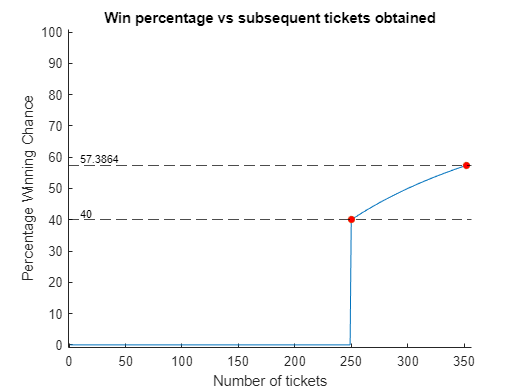

yline(max(Percentage_Range),"k--")
yline(Points_of_Interest(1),"k--")
text([10 10],[Points_of_Interest(1) Points_of_Interest(2)],string(Points_of_Interest),'FontSize',8,'VerticalAlignment','bottom','HorizontalAlignment','left')
hold off

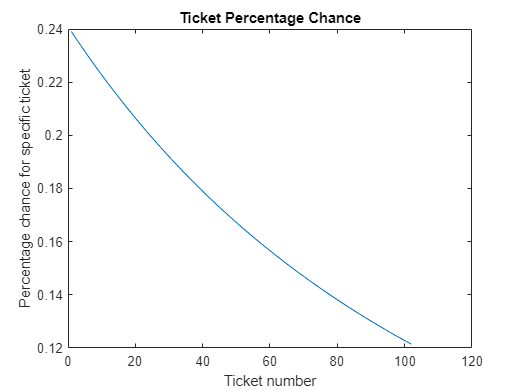


% There is a dropoff for subsequent ticket effectiveness where 1 ticket
% intrinsically gives the best chance per BNTX spent but you obviously want
% to maximise its effectiveness so there is a decay by popular game theory
Ticket_Viability = diff(Win_Probability_2);
plot(Ticket_Viability)
title("Ticket Percentage Chance")
ylabel("Percentage chance for specific ticket")
xlabel("Ticket number")